# Dynamics - Euler-Lagrange II

Dynamics of one-legged dodo-modell in stance-phase.

The following assumptions were made:

- Spring-force of leg is modelled as internal kinetic energy

- Contact with ground is ideal (e=1 for impulse)

- LOREM IPSUM

clear all;
clc;

## 1) Parameters

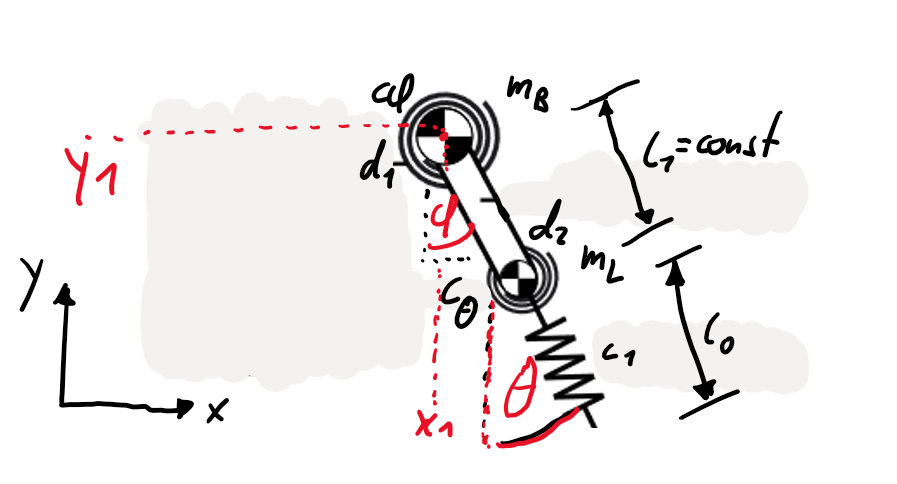

#### 1_1) Physical parameters

syms m_L; % kg; Mass of leg, concentrated as point mass in knee
syms m_B; % kg; Mass of upper body, concentrated as point mass in hip

syms d_1; % N*s/rad; Rotational damper in hip
syms d_2; % N*s/rad; Rotational damper in knee

syms c_phi; % N/rad; Rotational spring in hip
syms c_theta; % N/rad; Rotational spring in knee
syms c_1; % N/m; Translational spring attached to knee

syms l_1; % m, Length of leg-segment between knee and hip
syms l_0; % m, Initial length of translational spring at knee

syms g_earth;
g = [0; g_earth]; % m/s^2; Gravitational acceleration

#### 1_2) Dynamic parameters

syms t x_1(t) y_1(t) phi(t) theta(t);
q = [x_1; y_1; phi; theta]; % Vector of generalized coordinates, see picture for more information

syms dx_1(t) dy_1(t) dphi(t) dtheta(t); % Variables for velocity of generalized coordiantes, used later for Euler-Lagrange function

## 2) Position vectors of point masses


r_mB = [x_1; y_1]; %Position of hip
r_mL = [x_1 + sin(phi)*l_1; y_1 - cos(phi)*l_1]; %Position of knee

%Velocity
d_r_mB = diff(r_mB);
d_r_mL = diff(r_mL);
%Acceleration
dd_r_mB = diff(d_r_mB);
dd_r_mL = diff(d_r_mL);

## 3) Terms for Euler-Lagrange

#### 3_1) Kinetic_Energy

T_B = 0.5 * m_B * (d_r_mB' * d_r_mB); % Kinetic energy of hip

T_L = 0.5 * m_L * (d_r_mL' * d_r_mL); % Kinetic energy of knee

T = simplify(T_B + T_L); % Total kinetic energy

#### 3_2) Potential_Energy

V_G = - m_B * (r_mB' * g) - m_L * (r_mL' * g); % Gravitational potential energy

V_rotC = c_phi * phi + c_theta * theta; % Rotational spring energy

l = sqrt(r_mL' * r_mL); % m; current length of translational spring
V_c = c_1 * (l - l_0); % Translational spring energy

V = simplify(V_G + V_rotC + V_c); % Total potential energy

#### 3_3) Non-conservative forces

X_1 = -d_1 * diff(phi) * [-cos(phi); - sin(phi)];
X_2 = -d_2 * diff(theta) * [-cos(theta); - sin(theta)];

%Help variables for calculating the differentiations
xx = sym('x_1');
yy = sym('y_1');
phiphi = sym('phi');
thetatheta = sym('theta');

dx_r_mB = subs(diff(subs(r_mB,x_1,xx),xx),xx,x_1);
dx_r_mL = subs(diff(subs(r_mL,x_1,xx),xx),xx,x_1);

dy_r_mB = subs(diff(subs(r_mB,y_1,yy),yy),yy,y_1);
dy_r_mL = subs(diff(subs(r_mL,y_1,yy),yy),yy,y_1);

dphi_r_mB = subs(diff(subs(r_mB,phi,phiphi),phiphi),phiphi,phi);
dphi_r_mL = subs(diff(subs(r_mL,phi,phiphi),phiphi),phiphi,phi);

dtheta_r_mB = subs(diff(subs(r_mB,theta,thetatheta),thetatheta),thetatheta,theta);
dtheta_r_mL = subs(diff(subs(r_mL,theta,thetatheta),thetatheta),thetatheta,theta);


Q_nc_x = (dx_r_mB)' * X_1 + (dx_r_mL)' * X_2;
Q_nc_y = (dy_r_mB)' * X_1 + (dy_r_mL)' * X_2;
Q_nc_phi = (dphi_r_mB)' * X_1 + (dphi_r_mL)' * X_2;
Q_nc_theta = (dtheta_r_mB)' * X_1 + (dtheta_r_mL)' * X_2;

Q_nc = simplify([Q_nc_x; Q_nc_y; Q_nc_phi; Q_nc_theta]); %Vector of non-conservative forces

## 4) Applying Euler-Lagrange II

%Adjusting T, V, Q for use in matlab toolbox

T = subs(T, diff(x_1), dx_1);
T = subs(T, diff(y_1), dy_1);
T = subs(T, diff(phi), dphi);
T = subs(T, diff(theta), dtheta)

$$T(t) = \frac{m_{B}\,\left(\bar{{\mathrm{dx}}_{1}\left(t\right)}\,{\mathrm{dx}}_{1}\left(t\right)+\bar{{\mathrm{dy}}_{1}\left(t\right)}\,{\mathrm{dy}}_{1}\left(t\right)\right)}{2}+\frac{m_{L}\,\left(\left({\mathrm{dx}}_{1}\left(t\right)+l_{1}\,\cos\left(\varphi \left(t\right)\right)\,\mathrm{dphi}\left(t\right)\right)\,\left(\bar{{\mathrm{dx}}_{1}\left(t\right)}+\bar{\mathrm{dphi}\left(t\right)}\,\cos\left(\bar{\varphi \left(t\right)}\right)\,\bar{l_{1}}\right)+\left({\mathrm{dy}}_{1}\left(t\right)+l_{1}\,\sin\left(\varphi \left(t\right)\right)\,\mathrm{dphi}\left(t\right)\right)\,\left(\bar{{\mathrm{dy}}_{1}\left(t\right)}+\bar{\mathrm{dphi}\left(t\right)}\,\sin\left(\bar{\varphi \left(t\right)}\right)\,\bar{l_{1}}\right)\right)}{2}$$


V = subs(V, diff(x_1), dx_1);
V = subs(V, diff(y_1), dy_1);
V = subs(V, diff(phi), dphi);
V = subs(V, diff(theta), dtheta)

$$V(t) = \begin{array}{l} c_{\varphi }\,\varphi \left(t\right)-c_{1}\,\left(l_{0}-\sqrt{\left(y_{1}\left(t\right)-l_{1}\,\cos\left(\varphi \left(t\right)\right)\right)\,\sigma_{1}+\left(x_{1}\left(t\right)+l_{1}\,\sin\left(\varphi \left(t\right)\right)\right)\,\left(\bar{x_{1}\left(t\right)}+\sin\left(\bar{\varphi \left(t\right)}\right)\,\bar{l_{1}}\right)}\right)+c_{\theta }\,\theta \left(t\right)-g_{\mathrm{earth}}\,m_{B}\,\bar{y_{1}\left(t\right)}-g_{\mathrm{earth}}\,m_{L}\,\sigma_{1}\\ \mathrm{where}\\ \sigma_{1}=\bar{y_{1}\left(t\right)}-\cos\left(\bar{\varphi \left(t\right)}\right)\,\bar{l_{1}} \end{array}$$


Q_nc = subs(Q_nc, diff(x_1), dx_1);
Q_nc = subs(Q_nc, diff(y_1), dy_1);
Q_nc = subs(Q_nc, diff(phi), dphi);
Q_nc = subs(Q_nc, diff(theta), dtheta)

$$Q\_nc(t) = \left(\begin{array}{c} d_{1}\,\cos\left(\varphi \left(t\right)\right)\,\mathrm{dphi}\left(t\right)+d_{2}\,\cos\left(\theta \left(t\right)\right)\,\mathrm{dtheta}\left(t\right)\\ d_{1}\,\sin\left(\varphi \left(t\right)\right)\,\mathrm{dphi}\left(t\right)+d_{2}\,\sin\left(\theta \left(t\right)\right)\,\mathrm{dtheta}\left(t\right)\\ d_{2}\,\cos\left(\bar{\varphi \left(t\right)}-\theta \left(t\right)\right)\,\bar{l_{1}}\,\mathrm{dtheta}\left(t\right)\\ 0 \end{array}\right)$$

%Building the Lagrange-Function

%Calculatin dt_dq_T
dq_T_x = subs(diff(subs(T,x_1,xx),xx),xx,x_1);
dq_T_y = subs(diff(subs(T,y_1,yy),yy),yy,y_1);
dq_T_phi = subs(diff(subs(T,phi,phiphi),phiphi),phiphi,phi);
dq_T_theta = subs(diff(subs(T,theta,thetatheta),thetatheta),thetatheta,theta);

dq_T = [dq_T_x; dq_T_y; dq_T_phi; dq_T_theta];

dq_dq_T = diff(dq_T)


%Calculating dT/ddq
dxx = sym('dx_1');
dyy = sym('dy_1');
dphiphi = sym('dphi');
dthetatheta = sym('dtheta');

ddq_T_dx = subs(diff(subs(T,dx_1,dxx),dxx),dxx,dx_1);
ddq_T_dy = subs(diff(subs(T,dy_1,dyy),dyy),dyy,dy_1);
ddq_T_dphi = subs(diff(subs(T,dphi,dphiphi),dphiphi),dphiphi,dphi);
ddq_T_dtheta = subs(diff(subs(T,dtheta,dthetatheta),dthetatheta),dthetatheta,dtheta);

ddq_T = [ddq_T_dx; ddq_T_dy; ddq_T_dphi; ddq_T_dtheta]

$$ddq\_T(t) = \begin{array}{l} \left(\begin{array}{c} \frac{m_{B}\,\left(\bar{{\mathrm{dx}}_{1}\left(t\right)}+{\mathrm{dx}}_{1}\left(t\right)\right)}{2}+\frac{m_{L}\,\left(\bar{{\mathrm{dx}}_{1}\left(t\right)}+{\mathrm{dx}}_{1}\left(t\right)+\sigma_{4}+\sigma_{2}\right)}{2}\\ \frac{m_{B}\,\left(\bar{{\mathrm{dy}}_{1}\left(t\right)}+{\mathrm{dy}}_{1}\left(t\right)\right)}{2}+\frac{m_{L}\,\left(\bar{{\mathrm{dy}}_{1}\left(t\right)}+{\mathrm{dy}}_{1}\left(t\right)+\sigma_{3}+\sigma_{1}\right)}{2}\\ \frac{m_{L}\,\left(\sigma_{5}\,\bar{l_{1}}\,\left({\mathrm{dy}}_{1}\left(t\right)+\sigma_{1}\right)+l_{1}\,\cos\left(\varphi \left(t\right)\right)\,\left(\bar{{\mathrm{dx}}_{1}\left(t\right)}+\sigma_{4}\right)+l_{1}\,\sin\left(\varphi \left(t\right)\right)\,\left(\bar{{\mathrm{dy}}_{1}\left(t\right)}+\sigma_{3}\right)+\sigma_{6}\,\bar{l_{1}}\,\left({\mathrm{dx}}_{1}\left(t\right)+\sigma_{2}\right)\right)}{2}\\ 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=l_{1}\,\sin\left(\varphi \left(t\right)\right)\,\mathrm{dphi}\left(t\right)\\ \sigma_{2}=l_{1}\,\cos\left(\varphi \left(t\right)\right)\,\mathrm{dphi}\left(t\right)\\ \sigma_{3}=\bar{\mathrm{dphi}\left(t\right)}\,\sigma_{5}\,\bar{l_{1}}\\ \sigma_{4}=\bar{\mathrm{dphi}\left(t\right)}\,\sigma_{6}\,\bar{l_{1}}\\ \sigma_{5}=\sin\left(\bar{\varphi \left(t\right)}\right)\\ \sigma_{6}=\cos\left(\bar{\varphi \left(t\right)}\right) \end{array}$$


%Calculatin dV/dq
dq_V_x = subs(diff(subs(V,x_1,xx),xx),xx,x_1);
dq_V_y = subs(diff(subs(V,y_1,yy),yy),yy,y_1);
dq_V_phi = subs(diff(subs(V,phi,phiphi),phiphi),phiphi,phi);
dq_V_theta = subs(diff(subs(V,theta,thetatheta),thetatheta),thetatheta,theta);

dq_V = [dq_V_x; dq_V_y; dq_V_phi; dq_V_theta]

$$dq\_V(t) = \begin{array}{l} \left(\begin{array}{c} \frac{c_{1}\,\left(\bar{x_{1}\left(t\right)}+x_{1}\left(t\right)+\sigma_{4}+\sigma_{6}\,\bar{l_{1}}\right)}{\sigma_{1}}\\ \frac{c_{1}\,\left(\bar{y_{1}\left(t\right)}+y_{1}\left(t\right)-\sigma_{5}-\sigma_{7}\,\bar{l_{1}}\right)}{\sigma_{1}}-g_{\mathrm{earth}}\,m_{L}-g_{\mathrm{earth}}\,m_{B}\\ c_{\varphi }+\frac{c_{1}\,\left(\sigma_{7}\,\bar{l_{1}}\,\left(x_{1}\left(t\right)+\sigma_{4}\right)+\sigma_{6}\,\bar{l_{1}}\,\left(y_{1}\left(t\right)-\sigma_{5}\right)+l_{1}\,\cos\left(\varphi \left(t\right)\right)\,\sigma_{2}+l_{1}\,\sin\left(\varphi \left(t\right)\right)\,\sigma_{3}\right)}{\sigma_{1}}-g_{\mathrm{earth}}\,m_{L}\,\sigma_{6}\,\bar{l_{1}}\\ c_{\theta } \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=2\,\sqrt{\left(y_{1}\left(t\right)-\sigma_{5}\right)\,\sigma_{3}+\left(x_{1}\left(t\right)+\sigma_{4}\right)\,\sigma_{2}}\\ \sigma_{2}=\bar{x_{1}\left(t\right)}+\sigma_{6}\,\bar{l_{1}}\\ \sigma_{3}=\bar{y_{1}\left(t\right)}-\sigma_{7}\,\bar{l_{1}}\\ \sigma_{4}=l_{1}\,\sin\left(\varphi \left(t\right)\right)\\ \sigma_{5}=l_{1}\,\cos\left(\varphi \left(t\right)\right)\\ \sigma_{6}=\sin\left(\bar{\varphi \left(t\right)}\right)\\ \sigma_{7}=\cos\left(\bar{\varphi \left(t\right)}\right) \end{array}$$



%lagrange = dt_dq_T + ddq_T + dq_V - Q_nc;